# **Acoustic Echo Cancellation (AEC) System**

We will simulate an acoustic environment with a fully-duplex transmission of speech for audio teleconferencing, and immitate real-time processing where we will implement **AEC **and analyze the results.

## **Introduction**

Acoustic echo cancellation is important for audio teleconferencing when simultaneous communication (or full-duplex transmission) of speech is necessary. In acoustic echo cancellation, a measured microphone signal $m(n)$ contains two signals:

- The near-end speech signal $v(n)$

- The far-end echoed speech signal $d(n)$

The goal is to remove the far-end echoed speech signal, $d(n)$ from the microphone signal so that only the near-end speech signal is transmitted.

## Room Impulse Response(RIR) modeling:

We will be modeling the acoustics of the loudspeaker-to-microphone signal path where the speakerphone is located. We will be using a long impulse response filter to describe the characteristics of the room.

the below script generates a RIR with an assumption of a system sample rate of 16000 Hz.

fs = 16000;
M = fs/2 + 1;
frameSize = 2048;

[B,A] = cheby2(4,20,[0.1 0.7]);
impulseResponseGenerator = dsp.IIRFilter('Numerator',[zeros(1,6) B], ...
    'Denominator',A);

FVT = fvtool(impulseResponseGenerator);  % Analyze the filter

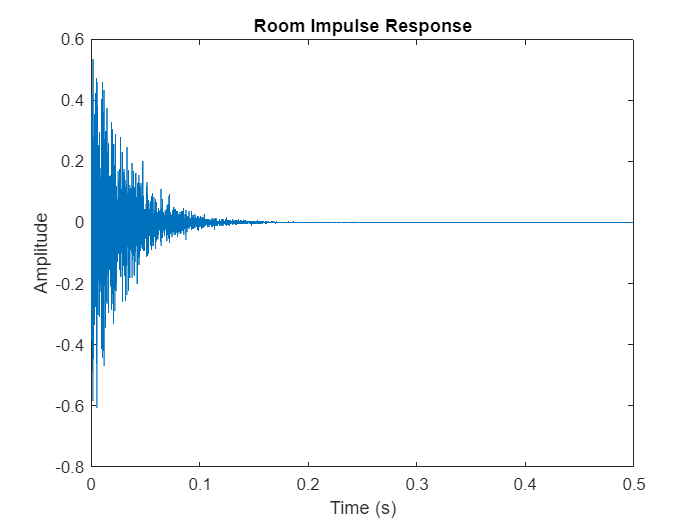

roomImpulseResponse = impulseResponseGenerator( ...
    (log(0.99*rand(1,M)+0.01).*sign(randn(1,M)).*exp(-0.002*(1:M)))');
roomImpulseResponse = roomImpulseResponse/norm(roomImpulseResponse)*4;
room = dsp.FIRFilter('Numerator', roomImpulseResponse');

fig = figure;
plot(0:1/fs:0.5, roomImpulseResponse);
xlabel('Time (s)');
ylabel('Amplitude');
title('Room Impulse Response');

fig.Color = [1 1 1];

## **Near-End Speech Signal**

The teleconferencing system's user is typically located near the system's microphone. 

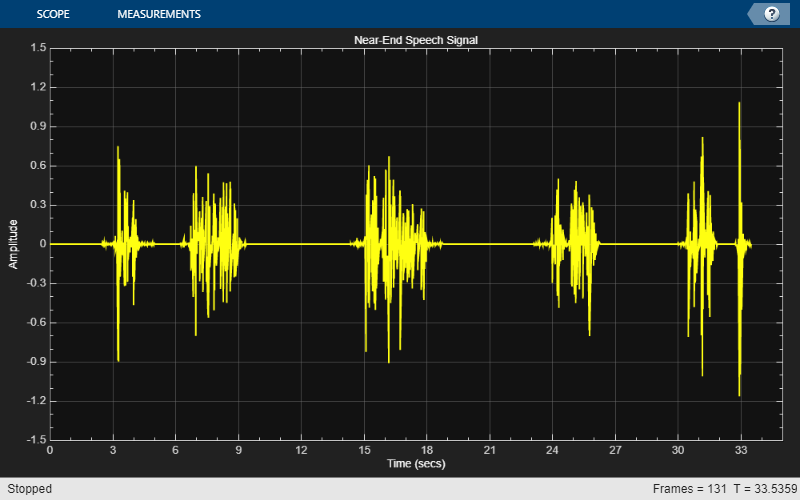

load nearspeech

player = audioDeviceWriter('SupportVariableSizeInput', true, ...
    'BufferSize', 512, 'SampleRate', fs);

nearSpeechSrc = dsp.SignalSource('Signal',v,'SamplesPerFrame',frameSize);

nearSpeechScope = timescope('SampleRate', fs, 'TimeSpanSource','Property',...
    'TimeSpan', 35, 'TimeSpanOverrunAction', 'Scroll', ...
    'YLimits', [-1.5 1.5], ...
    'BufferLength', length(v), ...
    'Title', 'Near-End Speech Signal', ...
    'ShowGrid', true);

% Stream processing loop
while(~isDone(nearSpeechSrc))
    % Extract the speech samples from the input signal
    nearSpeech = nearSpeechSrc();
    % Send the speech samples to the output audio device
    player(nearSpeech);
    % Plot the signal
    nearSpeechScope(nearSpeech);
end
release(nearSpeechScope)

## Far-End Speech Signal

In a teleconferencing system, a voice travels out the loudspeaker, bounces around in the room, and then is picked up by the system's microphone. Modeling the echoed version of far-end speech which is picked by the microphone.

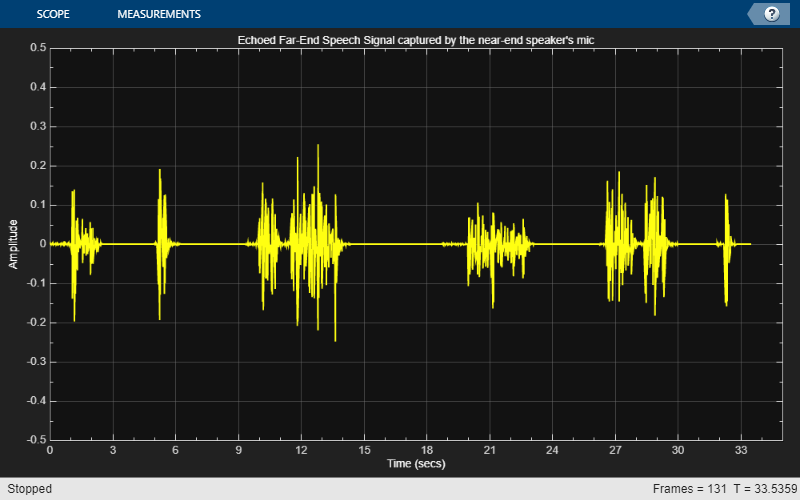

load farspeech
farSpeechSrc = dsp.SignalSource('Signal',x,'SamplesPerFrame',frameSize);

farSpeechSink = dsp.SignalSink;

farSpeechScope = timescope('SampleRate', fs, 'TimeSpanSource','Property',...
    'TimeSpan', 35, 'TimeSpanOverrunAction', 'Scroll', ...
    'YLimits', [-0.5 0.5], ...
    'BufferLength', length(x), ...
    'Title', "Echoed Far-End Speech Signal captured by the near-end speaker's mic", ...
    'ShowGrid', true);

% Stream processing loop
while(~isDone(farSpeechSrc))
    % Extract the speech samples from the input signal
    farSpeech = farSpeechSrc();
    % Add the room effect to the far-end speech signal
    farSpeechEcho = room(farSpeech);
    % Send the speech samples to the output audio device
    player(farSpeechEcho);
    % Plot the signal
    farSpeechScope(farSpeech);
    % Log the signal for further processing
    farSpeechSink(farSpeechEcho);
end
release(farSpeechScope);

## Microphone Signal

The signal at the microphone contains both the near-end speech and the far-end speech that has been echoed throughout the room.

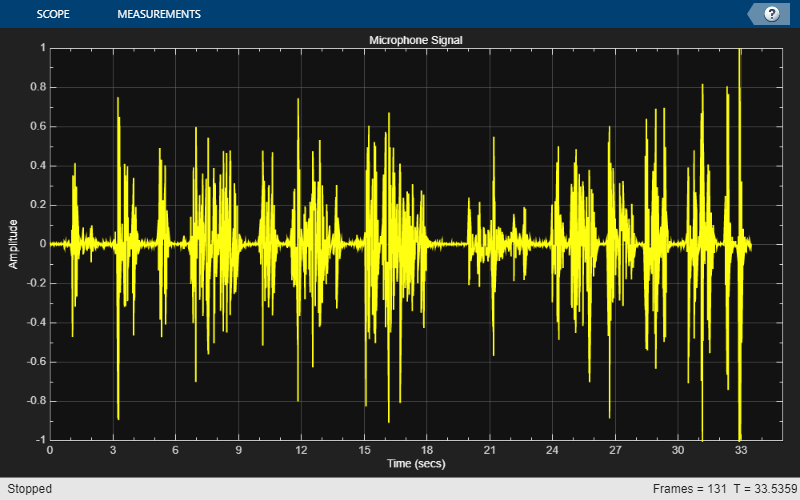

reset(nearSpeechSrc);
farSpeechEchoSrc = dsp.SignalSource('Signal', farSpeechSink.Buffer, ...
    'SamplesPerFrame', frameSize);

micSink = dsp.SignalSink;

micScope = timescope('SampleRate', fs,'TimeSpanSource','Property',...
    'TimeSpan', 35, 'TimeSpanOverrunAction', 'Scroll',...
    'YLimits', [-1 1], ...
    'BufferLength', length(x), ...
    'Title', 'Microphone Signal', ...
    'ShowGrid', true);

% Stream processing loop
while(~isDone(farSpeechEchoSrc))
    % Microphone signal = echoed far-end + near-end + noise
    micSignal = farSpeechEchoSrc() + nearSpeechSrc() + ...
        0.001*randn(frameSize,1);
    % Send the speech samples to the output audio device
    player(micSignal);
    % Plot the signal
    micScope(micSignal);
    % Log the signal
    micSink(micSignal);
end
release(micScope);

## Frequency-Domain Adaptive Filter (FDAF) Technique

% Construct the Frequency-Domain Adaptive Filter
echoCanceller = dsp.FrequencyDomainAdaptiveFilter('Length', 2048, ...
    'StepSize', 0.025, ...
    'InitialPower', 0.01, ...
    'AveragingFactor', 0.98, ...
    'Method', 'Unconstrained FDAF');

AECScope1 = timescope(4, fs, ...
    'LayoutDimensions', [4,1],'TimeSpanSource','Property', ...
    'TimeSpan', 35, 'TimeSpanOverrunAction', 'Scroll', ...
    'BufferLength', length(x));

AECScope1.ActiveDisplay = 1;
AECScope1.ShowGrid = true;
AECScope1.YLimits = [-1.5 1.5];
AECScope1.Title = 'Near-End Speech Signal';

AECScope1.ActiveDisplay = 2;
AECScope1.ShowGrid = true;
AECScope1.YLimits = [-1.5 1.5];
AECScope1.Title = 'Microphone Signal';

AECScope1.ActiveDisplay = 3;
AECScope1.ShowGrid = true;
AECScope1.YLimits = [-1.5 1.5];
AECScope1.Title = 'Output of Acoustic Echo Canceller mu=0.025';

AECScope1.ActiveDisplay = 4;
AECScope1.ShowGrid = true;
AECScope1.YLimits = [0 50];
AECScope1.YLabel = 'ERLE (dB)';
AECScope1.Title = 'Echo Return Loss Enhancement mu=0.025';

% Near-end speech signal
release(nearSpeechSrc);
nearSpeechSrc.SamplesPerFrame = frameSize;

% Far-end speech signal
release(farSpeechSrc);
farSpeechSrc.SamplesPerFrame = frameSize;

% Far-end speech signal echoed by the room
release(farSpeechEchoSrc);
farSpeechEchoSrc.SamplesPerFrame = frameSize;

## Echo Return Loss Enhancement (ERLE)

Using the near-end and far-end speech signals, we can compute the **echo return loss enhancement (ERLE)**, which is a smoothed measure of the amount (in dB) that the echo has been attenuated.

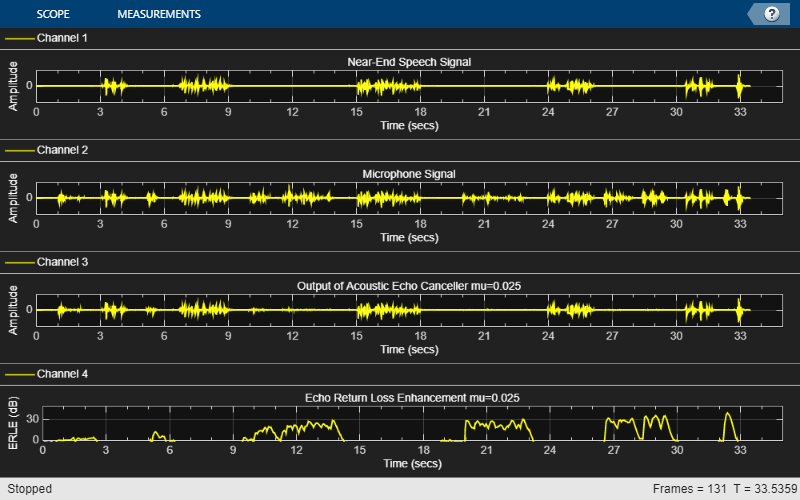

diffAverager = dsp.FIRFilter('Numerator', ones(1,1024));
farEchoAverager = clone(diffAverager);
setfilter(FVT,diffAverager);

micSrc = dsp.SignalSource('Signal', micSink.Buffer, ...
    'SamplesPerFrame', frameSize);

% Stream processing loop - adaptive filter step size = 0.025
while(~isDone(nearSpeechSrc))
    nearSpeech = nearSpeechSrc();
    farSpeech = farSpeechSrc();
    farSpeechEcho = farSpeechEchoSrc();
    micSignal = micSrc();
    % Apply FDAF
    [y,e] = echoCanceller(farSpeech, micSignal);
    % Send the speech samples to the output audio device
    player(e);
    % Compute ERLE
    erle = diffAverager((e-nearSpeech).^2)./ farEchoAverager(farSpeechEcho.^2);
    erledB = -10*log10(erle);
    % Plot near-end, far-end, microphone, AEC output and ERLE
    AECScope1(nearSpeech, micSignal, e, erledB);
end
release(AECScope1);

## Effects of Different Step Size Values

To get faster convergence, we can try using a larger step size value. However, this increase causes another effect: the adaptive filter is "misadjusted" while the near-end speaker is talking.

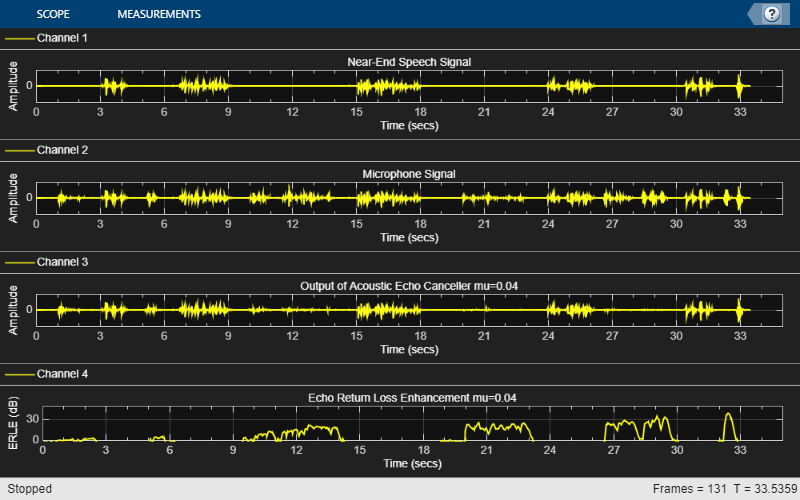

% Change the step size value in FDAF
reset(echoCanceller);
echoCanceller.StepSize = 0.04;

AECScope2 = clone(AECScope1);
AECScope2.ActiveDisplay = 3;
AECScope2.Title = 'Output of Acoustic Echo Canceller mu=0.04';
AECScope2.ActiveDisplay = 4;
AECScope2.Title = 'Echo Return Loss Enhancement mu=0.04';

reset(nearSpeechSrc);
reset(farSpeechSrc);
reset(farSpeechEchoSrc);
reset(micSrc);
reset(diffAverager);
reset(farEchoAverager);

% Stream processing loop - adaptive filter step size = 0.04
while(~isDone(nearSpeechSrc))
    nearSpeech = nearSpeechSrc();
    farSpeech = farSpeechSrc();
    farSpeechEcho = farSpeechEchoSrc();
    micSignal = micSrc();
    % Apply FDAF
    [y,e] = echoCanceller(farSpeech, micSignal);
    % Send the speech samples to the output audio device
    player(e);
    % Compute ERLE
    erle = diffAverager((e-nearSpeech).^2)./ farEchoAverager(farSpeechEcho.^2);
    erledB = -10*log10(erle);
    % Plot near-end, far-end, microphone, AEC output and ERLE
    AECScope2(nearSpeech, micSignal, e, erledB);
end

release(nearSpeechSrc);
release(farSpeechSrc);
release(farSpeechEchoSrc);
release(micSrc);
release(diffAverager);
release(farEchoAverager);
release(echoCanceller);
release(AECScope2);

## Echo Return Loss Enhancement Comparison

With a larger step size, the ERLE performance is not as good due to the misadjustment introduced by the near-end speech. To deal with this performance difficulty, acoustic echo cancelers include a detection scheme to tell when near-end speech is present and lower the step size value over these periods. Without such detection schemes, the performance of the system with the larger step size is not as good as the former, as can be seen from the ERLE plots.

## Latency Reduction Using Partitioning

Traditional FDAF is numerically more efficient than time-domain adaptive filtering for long impulse responses, but it imposes high latency, because the input frame size must be a multiple of the specified filter length. This can be unacceptable for many real-world applications. Latency may be reduced by using partitioned FDAF, which partitions the filter impulse response into shorter segments, applies FDAF to each segment, and then combines the intermediate results. The frame size in that case must be a multiple of the partition (block) length, thereby greatly reducing the latency for long impulse responses.

% Reduce the frame size from 2048 to 256
frameSize = 256;
nearSpeechSrc.SamplesPerFrame    = frameSize;
farSpeechSrc.SamplesPerFrame     = frameSize;
farSpeechEchoSrc.SamplesPerFrame = frameSize;
micSrc.SamplesPerFrame           = frameSize;
% Switch the echo canceller to Partitioned constrained FDAF
echoCanceller.Method      = 'Partitioned constrained FDAF';
% Set the block length to frameSize
echoCanceller.BlockLength = frameSize;

% Stream processing loop
while(~isDone(nearSpeechSrc))
    nearSpeech = nearSpeechSrc();
    farSpeech = farSpeechSrc();
    farSpeechEcho = farSpeechEchoSrc();
    micSignal = micSrc();
    % Apply FDAF
    [y,e] = echoCanceller(farSpeech, micSignal);
    % Send the speech samples to the output audio device
    player(e);
    % Compute ERLE
    erle = diffAverager((e-nearSpeech).^2)./ farEchoAverager(farSpeechEcho.^2);
    erledB = -10*log10(erle);
    % Plot near-end, far-end, microphone, AEC output and ERLE
    AECScope2(nearSpeech, micSignal, e, erledB);
end